load toy2.dat
X = [ones(10, 1), toy2(:, 1:2)]

X =     1.0000    2.0000    3.0000
    1.0000    3.0000    2.0000
    1.0000    3.0000    6.0000
    1.0000    6.5000    4.5000
    1.0000    5.0000    3.0000
    1.0000    7.0000    3.0000
    1.0000    5.0000    6.0000
    1.0000    8.0000    6.0000
    1.0000    9.5000    5.0000
    1.0000    9.0000    7.0000


t = toy2(:, 3)

t =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


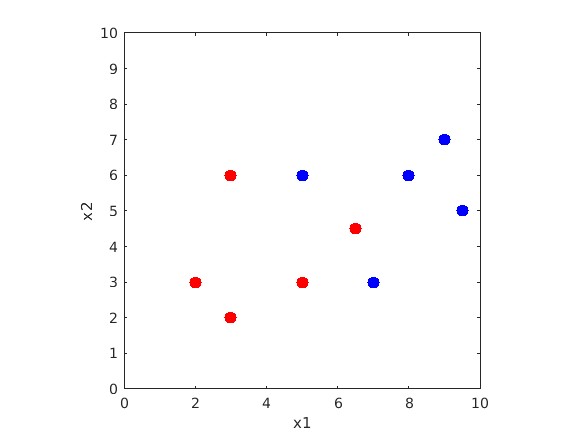

W1 =     0.0925    0.3169    0.3497
    0.0924    0.3129    0.3526
   -4.1398    0.5345    0.3383


W2 =    -0.7095   -0.6403   -0.6369    4.2649


% Plot the data
figure(1); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]); ylim([0 10]); 
xlabel('x1'); ylabel('x2')
axis square

%rng('default')
[Whidden, Wout] = errorBackpropTwoLayer(X, 3, t);
Whidden

Whidden =    -4.4009   -0.0716    0.9537
    1.2161   -1.3580    2.2032
   -0.2241    1.6550   -1.0519


Wout

Wout =     0.3184    5.1867   -4.4822    4.0308


%rng('default')
[Whidden, Wout] = errorbackpropschool(X, t);
Whidden

Whidden =     0.0920    0.3100    0.3554
    0.0908    0.3172    0.3493
   -4.1398    0.5345    0.3383


Wout

Wout =    -0.7112   -0.6383   -0.6372    4.2649


 % Calculate learned values
 learnedY = @(X) sigmoid(Wout * [ones(1, 10000); tanh(Whidden * X')]) ; %yFunc(Whidden, Wout, 10000);
 
 x1 = linspace(0, N);
 x2 = x1; 
 [x1 x2] = meshgrid(x1, x2);
 xs = [ones(10000, 1), x1(:), x2(:)];
 
 learnedY_values = learnedY(xs)

learnedY_values =     0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0009    0.0014


size(learnedY_values)

ans =            1       10000


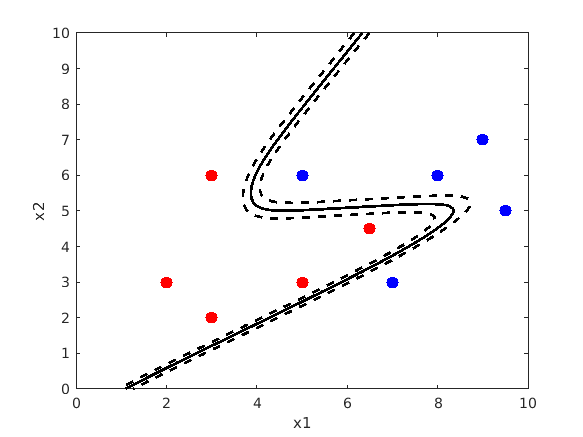




% Plot the learned function
figure(1); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]); ylim([0 10]); 
xlabel('x1'); ylabel('x2')

figure(1); hold on
 
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.27, 0.73], '--k', 'LineWidth', 2); hold on
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.5, 0.5], 'k', 'LineWidth', 2); 


% Calculate learned values
 learnedY = @(X) sigmoid(Wout * [ones(1, 10000); tanh(Whidden * X')]) ; %yFunc(Whidden, Wout, 10000);
 
 x1 = linspace(0, N);
 x2 = x1; 
 [x1 x2] = meshgrid(x1, x2);
 xs = [ones(10000, 1), x1(:), x2(:)];
 
 learnedY_values = learnedY(xs)

learnedY_values =     0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0005    0.0008    0.0013


size(learnedY_values)

ans =            1       10000


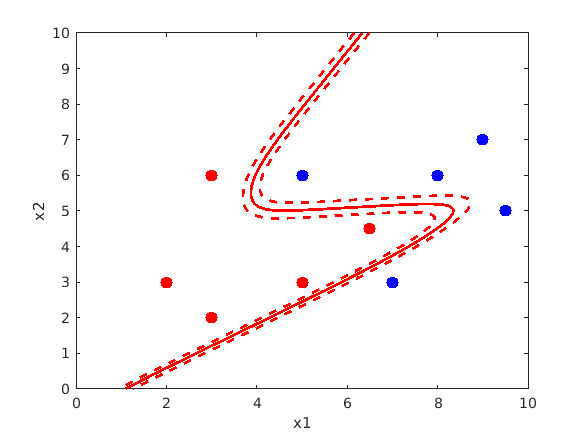




% Plot the learned function
figure(1); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]); ylim([0 10]); 
xlabel('x1'); ylabel('x2')

figure(1); hold on
 
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.27, 0.73], '--r', 'LineWidth', 2); hold on
contour(x1 ,x2, reshape(learnedY_values, 100, 100), [0.5, 0.5], 'r', 'LineWidth', 2); 